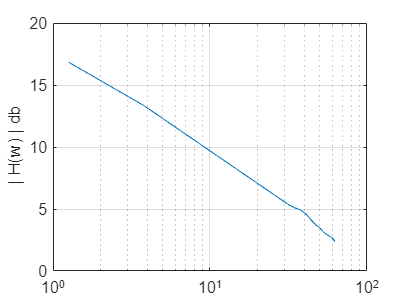

time_x = {senf020a200Ent_Time, senf060a200Ent_Time, senf500a200Ent_Time, senf550a200Ent_Time, senf600a200Ent_Time, senf650a200Ent_Time, senf700a200Ent_Time, senf750a200Ent_Time, senf800a200Ent_Time, senf850a200Ent_Time, senf900a200Ent_Time, senf950a200Ent_Time, senf1000a200Ent_Time};
time_y = {senf020a200Sai_Time(:,1), senf060a200Sai_Time(:,1), senf500a200Sai_Time(:,1), senf550a200Sai_Time(:,1), senf600a200Sai_Time(:,1), senf650a200Sai_Time(:,1), senf700a200Sai_Time(:,1), senf750a200Sai_Time(:,1), senf800a200Sai_Time(:,1), senf850a200Sai_Time(:,1), senf900a200Sai_Time(:,1), senf950a200Sai_Time(:,1), senf1000a200Sai_Time(:,1)};

x = {senf020a200Ent_Value, senf060a200Ent_Value, senf500a200Ent_Value, senf550a200Ent_Value, senf600a200Ent_Value, senf650a200Ent_Value, senf700a200Ent_Value, senf750a200Ent_Value, senf800a200Ent_Value, senf850a200Ent_Value, senf900a200Ent_Value, senf950a200Ent_Value, senf1000a200Ent_Value};
y = {senf020a200Sai_Value(:,1), senf060a200Sai_Value(:,1), senf500a200Sai_Value(:,1), senf550a200Sai_Value(:,1), senf600a200Sai_Value(:,1), senf650a200Sai_Value(:,1), senf700a200Sai_Value(:,1), senf750a200Sai_Value(:,1), senf800a200Sai_Value(:,1), senf850a200Sai_Value(:,1), senf900a200Sai_Value(:,1), senf950a200Sai_Value(:,1), senf1000a200Sai_Value(:,1)};


graf_init = 1;
graf_end = 13;

range_time_x = zeros(length(0:0.01:1), graf_end-graf_init+1);
range_x = zeros(length(0:0.01:1), graf_end-graf_init+1);

for i = graf_init:graf_end
    for j = 0:100
        range_time_x(j+1, i)= time_x{i}(length(time_x{i})-100+j)-time_x{i}(length(time_x{i})-100);
        range_x(j+1, i)= x{i}(length(time_x{i})-100+j);
    end
end

range_time_y = zeros(length(0:0.01:1), graf_end-graf_init+1);
range_y = zeros(length(0:0.01:1), graf_end-graf_init+1);

for i = graf_init:graf_end
    for j = 0:100
        range_time_y(j+1, i)= time_y{i}(length(time_y{i})-100+j)-time_y{i}(length(time_y{i})-100);
        range_y(j+1, i)= y{i}(length(time_y{i})-100+j);
    end
end

%Essa parte o Paulo fez
%N deleta oq veio antes pq eu uso no loop

%pegando as frequências medidas
%frequencySample

%frequencies = [1, 2, 3, 4, 5, 6, 7, 8, 9, 10];
frequencies = [0.2, 0.6, 5, 5.5, 6, 6.5, 7, 7.5, 8, 8.5, 9, 9.5, 10];
omega = 2*pi.*frequencies;

Xrms = frequencies;
n = 1;
for i=frequencies
    Xfreq = range_x(:,n);
    Xrms(n) = rms(Xfreq);
    n = n + 1;
end

Yrms = frequencies;
n = 1;
for i=frequencies
    Yfreq = range_y(:,n);
    Yrms(n) = rms(Yfreq);
    n = n + 1;
end

Hrms = frequencies;
n=1;
for i=frequencies
    Hrms(n) = Yrms(n)/Xrms(n);
    n = n + 1;
end

db=20*log10(Hrms);
semilogx(2*pi*frequencies,Hrms)
xlabel('w')
ylabel(' | H(w) | db')
grid on

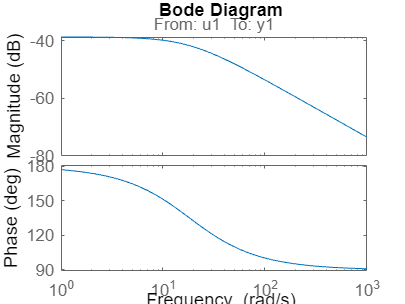


bodeData = iddata(transpose(Hrms), transpose(omega), 0.01);

order = 1;

test = tfest(bodeData, order);
bode(test);

%% Aqui acaba a parte do Paulo